# Tire Manufacturing 

We are a manager in charge of a machine that is used to produce tires. The machine has two bladders inside, to create two tires simultaneously. Anytime we want to produce new tires, there is a likelihood of the bladders inside the machine to fail, leading to produce junk, and also bladder going useless after that point. Hence, after each tire produced with one bladder, that bladder is assumed to have a higher likelihood of failure.

The cost of a new bladder is c_1.

The cost of a scrap tire to the company is c_2.

To change a bladder, the machine has to be stopped and repaired by a mechanic. The mechanic has a fee for fixing the machine and replacing bladders, c_3.

Additionally, while the machine is open to be fixed in operational hours, no tire is produced. Hence, there is a cost of lost production time, c_4.

If the machine is repaired outside the operational hours, the time cost will not be incurred. Additionally, no scrap tire will be produced. Hence, c_2 and c_4 are not present as a cost in this case.

Say we got an order of N tires, and in our machine there is two bladders, which have been used i and j many tires before. Let $f_N(i,j)$ be the total optimal cost of producing N tires, with the initial state $(i,j)$. Then, by using the Principle of Optimality, we can calculate $f_N(i,j)$ by looking at the initial stage and iterating over previously calculated costs, $f_{N-1}(\tilde{i},\tilde{j})$ and $f_{N-2}(i^*,j^*)$ for potentially different $(\tilde{i},\tilde{j})$, $(i^*, j^*)$. The full derivation will be done later.

The limits of i and j are decided by the probability of success vector that's given or estimated. In the example below, it is assumed that after producing 6 tires, a bladder is not viable for use anymore. Our main goal is to reduce the average cost of producing N tires starting with bladders which have produced i and j many tires. 

At every stage of production, we can choose to apply the controls below

- Change both of the bladders at the same time outside operation hours (Replace Both)

- Change the first bladder (Replace First) 

- Change the second bladder (Replace Second)

-  Try to produce two tires (Produce Both)

After choosing the control that results in the minimum cost, we will have the total cost starting at state $(i,j)
$ to produce N tires, $f_N(i,j)$.

To see the results of the controls, we will see the outcomes of each control, and quantify the total cost of each control, to later choose whichever gives the minimum. 

- RB(Replacing Both Bladders): Two bladder cost will occur, and also the mechanic will ask for a fee for opening the machine. These changes will be done outside the operational hours, so there will be no cost associated to downtime. Additionally, there will be no scrap to get rid of. Yet, there will be no tires produced. Hence, there will be the same number of produced tires with new bladders. Hence, the total cost will now be $2c_1 + c_3 + f_N(0,0)$

- RF(Replacing First Bladder): One bladder will be changed, and mechanic will ask for a fee. Similar to the previous control, there will be no tires to be scrapped and no lost time. Again, no tire will be produced, but one of the states will convert to zero. Hence, the total cost will be $c_1 + c_3 + f_N(0,j)$ when we are at state $(i,j)
$.

- RS(Replacing Second Bladder): Exactly the same scenario with the previous control, only for the second bladder. Hence, the total cost will be $c_1 + c_3 + f_N(i,0)$when we are at state $(i,j)
$.

- PB(Produce Both): This control has four terms averaged by the likelihood of success for each outcome. A detailed explanation is given below:

    Assume we start on an arbitrary state $(i,j)
$ to produce $N
$ tires. 

- Suppose that we produced two tires. We are at a new stage $N-2$, and both bladders have now produced one more tire, resulting in the state $(i+1,j+1)$. Since producing two tires has a likelihood of $p_i\, p_j$, the weighted outcome out of this case is $p_i\, p_j\;f_{N-2}(i+1,j+1)$. 

- WLOG suppose we produce one tire with the bladder of state i, and the other one fails. Then the new state can be chosen from one of two: since the second bladder has failed,it produced scrap and it cannot produce new tires. So, the machine will be repaired and the second bladder will be renewed. In this case, we have a choice on changing the first bladder as well. Since the machine is already stripped down, the cost of time has occurred and the fee for the mechanic has to be paid. If changing the first bladder together with the second bladder is less costly than changing only the second bladder, then we can choose to replace both bladders and reduce the expected cost. Then the total cost in this case will be $\min \{c_1 + c_2 + c_3 + c_4 + f_{N-1}(i+1,0)\,,\,2c_1 + c_2 + c_3 + c_4 + f_{N-1}(0,0)\}$. Hence, the term of expected cost of the control PB coming from this case is $p_i (1-p_j)\min \{c_1 + c_2 + c_3 + c_4 + f_{N-1}(i+1,0)\,,\,2c_1 + c_2 + c_3 + c_4 + f_{N-1}(0,0)\}$

- In the countercase of 2, i.e. the first bladder failing, the exact same scenario happens with states replaced. Hence, the term of expected cost of the control PB coming from this case is $(1-p_i) p_j\min \{c_1 + c_2 + c_3 + c_4 + f_{N-1}(0,j+1)\,,\,2c_1 + c_2 + c_3 + c_4 + f_{N-1}(0,0)\}$.

- Finally, suppose both bladders failed. Then there is no tire produced, two scraps have to be taken care of, and the machine will have to be repaired, resulting in two bladder costs, 2 scrap costs, repair cost and cost of loss time. On top of this, the stage hasn't changed. The term of expected cost of the control PB coming from this case is $(1-p_i)(1-p_j)[2c_1 + 2c_2 + c_3 + c_4 + f_N(0,0)]$

Hence, the control PB(Produce Both) has an expected cost of $p_i\, p_j\;f_{N-2}(i+1,j+1) \\ + \; p_i (1-p_j)\min \{c_1 + c_2 + c_3 + c_4 + f_{N-1}(i+1,0)\,,\,2c_1 + c_2 + c_3 + c_4 + f_{N-1}(0,0)\} \\ + \;(1-p_i) p_j\min \{c_1 + c_2 + c_3 + c_4 + f_{N-1}(0,j+1)\,,\,2c_1 + c_2 + c_3 + c_4 + f_{N-1}(0,0)\} \\ + \; (1-p_i)(1-p_j)[2c_1 + 2c_2 + c_3 + c_4 + f_N(0,0)]$

There are two caviats in the future calculations where we have to be meticulous. 

- Since each stage of the calculations require previous two steps, we will have to start setting up values for producing no tires, $N=0$ and producing one tire, $N=1$. Producing one tire requires its own controls setup since producing from both bladders is not the aim.

- The "renewed" states, i.e. at least one of $i$ and $j$ is equal to 0 have to be considered seperately from other states because they are required on the calculations of all the other states. On the guaranteed failure states we are at the boundary of all states, and so there is no $i+1$ or $j+1$ states to take values from in previous stages. 

(Maybe show how reaching a result is guaranteed in this mindset. Mold the principle of optimality to this case)

The results below show how this iterative method leads to 

- an average optimal cost of producing a tire, and 

- a fixed policy on each state to be applied and obtain the optimal average cost.

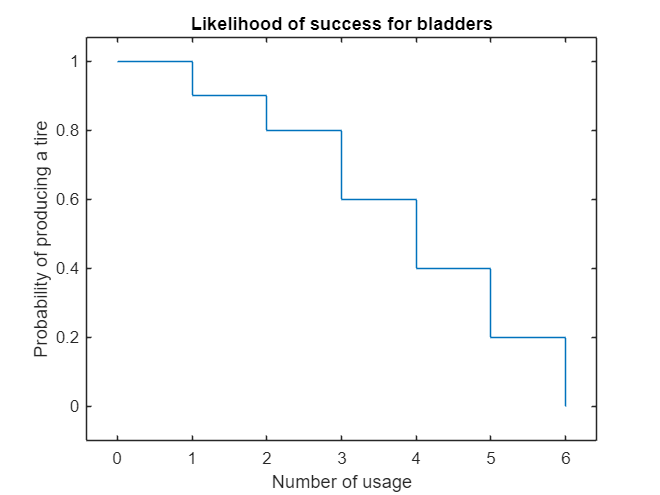

% probability of success p_i for a bladder which produced i tires, i==0:6
prob_success = [ 1 0.9 0.8 0.6 0.4 0.2 0 ];


stairs(0:6,prob_success)
axis padded
title("Likelihood of success for bladders")
xlabel("Number of usage")
ylabel("Probability of producing a tire")

% plot(prob_success,1:length(prob_success));
% should be decreasing  since items tire out over time, and so that length(prob_success)
% is useful in the later steps
lifetime = length(prob_success) - 1;

The word "lifetime" will be used as the maximum number of tires a bladder can produce.

fprintf("The lifetime of a bladder is " + num2str(lifetime) + ", i.e. a bladder is \nguaranteed to fail after producing "+num2str(lifetime)+" tires.");

The lifetime of a bladder is 6, i.e. a bladder is 
guaranteed to fail after producing 6 tires.

After a vector is given that represents the probability of success at each state of a bladder, the lifetime of a bladder is set to be the final state. Above, the bladders are assumed to fail no matter what after producing 6 tires, and so the lifetime of a bladder is 6.

The costs c_1 to c_4 are set below.

% Operational Costs 
c_1 = 50; % cost of purchasing a bladder
c_2 = 1; % cost of scrap per scrapped tire
c_3 = 2; % labor cost of stripping machines
c_4 = 3; % cost of lost production time

t_1 = "The cost of one bladder is: " + num2str(c_1);
t_2 = "The cost of scrapping a tire is: " + num2str(c_2);
t_3 = "The cost of mechanic is: " + num2str(c_3);
t_4 = "The cost of lost time is: " + num2str(c_4);
fprintf(t_1); 

The cost of one bladder is: 50

fprintf(t_2); 

The cost of scrapping a tire is: 1

fprintf(t_3); 

The cost of mechanic is: 2

fprintf(t_4);

The cost of lost time is: 3

#### Calculations Setup

% decide max. number of tires to be produced
max_production = 1000;
fprintf("From 0 to " + num2str(max_production)+", all stages will be calculated one by one");

From 0 to 1000, all stages will be calculated one by one

The number can be set to any natural number, but calculations are likely to consume expansive amounts of time for large numbers.

% prepare the matrices for each number of production from 0 to
% max_production
cost_matrices = zeros(lifetime+1,lifetime+1,max_production+1);
control_matrices = string(cost_matrices);

For each number of tires to be produced (i.e. for each stage in the process), a new matrix is created. In each of these matrices, there are $(lifetime+1)*(lifetime+1)$ entries, each representing a possible state we are in. $cost\_matrices(i,j,n+1)$ holds the total optimal cost $ f_n(i,j)$ for each $n \in \{ 1,2,... \,, N \}$ and states $i,j \in \{0,1,2,...\, ,lifetime\}$.

$control\_matrices(i,j,n+1)$ holds the control that returns $ f_n(i,j)$ for each $n \in \{ 1,2,... \,, N \}$ and states $i,j \in \{0,1,2,...\, ,lifetime\}$.

Remark: When we produce zero tires, there is no cost. Hence, $cost\_matrices(i,j,1)$, which is the matrix that holds the values of cost for stage zero, is comprised of only zeroes.

#### Calculating stage n=1

We're going to be producing only one tire. So, 

% Calculate f_1(i,j) as the base case, used for iterating f_2
one_tire_cost = zeros(lifetime+1,lifetime+1);
% States where at least one bladder is new gives zero cost; produce with
% the new bladder and you are guaranteed to finish the job with no cost
% because no replacement will be needed.

for i = 1:(lifetime+1)
    for j = 1:(lifetime+1)
        x_i = min(c_1 + c_2 + c_3 + c_4, (1-prob_success(j))*(c_1 + 2*c_2 + c_3 + c_4));
        x_j = min(c_1 + c_2 + c_3 + c_4, (1-prob_success(i))*(c_1 + 2*c_2 + c_3 + c_4));
        produce_with_i = (1-prob_success(i))*x_i; 
        produce_with_j = (1-prob_success(j))*x_j;
        replace_i = c_1 + c_3 + one_tire_cost(1,j);
        replace_j = c_1 + c_3 + one_tire_cost(i,1);
        replace_both = 2*c_1 + c_3 + one_tire_cost(1,1); % this is always more than replacing one bladder
        
        control_choices = [produce_with_i produce_with_j replace_i replace_j replace_both];
        cost_dummy = min(control_choices);
        one_tire_cost(i,j) = cost_dummy;
        if cost_dummy == produce_with_i
            if produce_with_i == produce_with_j 
                control_matrices(i,j,2) = "PE";
            else 
                control_matrices(i,j,2) = "PF";
            end
        elseif cost_dummy == produce_with_j
            control_matrices(i,j,2) = "PS";
        elseif cost_dummy == replace_i
            if replace_i == replace_j
                control_matrices(i,j,2) = "RE";
            else 
                control_matrices(i,j,2) = "RF";
            end
        elseif cost_dummy == replace_j
            control_matrices(i,j,2) = "RS";
        end
    end
end

% attain this one_tire_cost into cost_matrices(:,:,2)
cost_matrices(:,:,2) = one_tire_cost;

fprintf("Recall that the lifetime of a bladder is given to be "+num2str(lifetime)+".");

Recall that the lifetime of a bladder is given to be 6.

fprintf("Below is the expected costs for producing only one tire.")

Below is the expected costs for producing only one tire.

disp(cost_matrices(:,:,2));

         0         0         0         0         0         0         0
         0    0.5700    1.1400    2.2800    3.4200    4.5600    5.6000
         0    1.1400    2.2800    4.5600    6.8400    9.1200   11.2000
         0    2.2800    4.5600    9.1200   13.6800   18.2400   22.4000
         0    3.4200    6.8400   13.6800   20.5200   27.3600   33.6000
         0    4.5600    9.1200   18.2400   27.3600   36.4800   44.8000
         0    5.6000   11.2000   22.4000   33.6000   44.8000   52.0000




fprintf("Below is the histogram for the values the cost function \nat stage 1 takes.")

Below is the histogram for the values the cost function 
at stage 1 takes.

fprintf("The x-axis shows the values the cost function gets, and \nthe y-axis shows the frequency for those values.")

The x-axis shows the values the cost function gets, and 
the y-axis shows the frequency for those values.

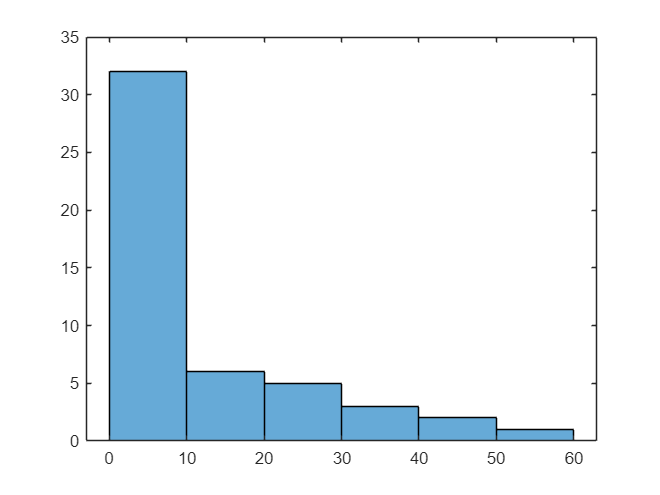

histogram(cost_matrices(:,:,2));

Say we want to get the expected cost of producing one tire when the first bladder has produced 3 times, and the second bladder has produced once. Recall that the states start from $(0,0)$ and goes all the way to $(lifetime, lifetime)$. Then we look at the fourth row, second column. Then $f_1(3,1) = 5.6$.

#### Calculating Later Stages

Recall that with the controls RB(Replace Both Bladders) and RF/RS(Replace First/Second Bladder), we don't produce any tires and at least one of $i$ or$j$ transition to 0. Hence, when we are setting up the cost matrices, at first we set up the entries which correspond to at least one bladder being renewed.

After these initial values are set, all "middle" states, i.e. the states where none of the bladders are new or at the end of its lifetime, are calculated straightforwardly, just by applying the control with the smallest cost.

For the "lifetime" states, the $lifetime+1$ states don't exist, so the data retrieval is likely to create problems if these states are calculated similarly to "middle" states.  

%% Iteration over number of tires

a = prob_success; 
for production = 3:max_production+1
    control_cost = zeros(lifetime+1,lifetime+1);
    
    % after every change, the new control_cost vector should be attributed
    % to the right z-index in cost_matrices because value retrievals are
    % all done on cost_matrices, sometimes self-referring to the same
    % matrix

    % setting up states with new bladders
    % both new
    control_cost(1,1) = cost_matrices(2,2,production-2);
    cost_matrices(:,:,production) = control_cost;
    control_matrices(1,1,production) = "PB";
    
    % first bladder is new
    for j = 2:lifetime
        produce_cost_1 = a(1)*a(j)*cost_matrices(2,j+1,production-2);
        produce_cost_2 = a(1)*(1-a(j))*min([(cost_matrices(2,1,production-1) + c_1 + c_2 + c_3 + c_4) (cost_matrices(1,1,production) + 2*c_1 + c_2 + c_3 + c_4)]);
        produce_cost = produce_cost_1 + produce_cost_2;
        replace_second_bladder = c_1 + c_3 + cost_matrices(1,1,production);
        replace_both_bladder = 2*c_1 + c_3 + cost_matrices(1,1,production);
        cost_dummy = [produce_cost replace_second_bladder replace_both_bladder];
        control_cost(1,j) = min([produce_cost replace_second_bladder replace_both_bladder]);
        if control_cost(1,j) == produce_cost
            control_matrices(1,j,production) = "PB";
        elseif control_cost(1,j) == replace_second_bladder
            control_matrices(1,j,production) = "RS";
        else
            control_matrices(1,j,production) = "RB";
        end
    end
    produce_cost = a(1)*(1-a(lifetime+1))*min([(cost_matrices(2,1,production-1) + c_1 + c_2 + c_3 + c_4) (cost_matrices(1,1,production) + 2*c_1 + c_2 + c_3 + c_4)]);
    replace_second_bladder = c_1 + c_3 + cost_matrices(1,1,production);
    replace_both_bladder = 2*c_1 + c_3 + cost_matrices(1,1,production);
    control_cost(1,lifetime+1) = min([produce_cost replace_second_bladder replace_both_bladder]);
    cost_matrices(:,:,production) = control_cost;
    if control_cost(1,lifetime+1) == produce_cost
        control_matrices(1,lifetime+1,production) = "PB";
    elseif control_cost(1,lifetime+1) == replace_second_bladder
        control_matrices(1,lifetime+1,production) = "RS";
    else
        control_matrices(1,lifetime+1,production) = "RB";
    end

    % second bladder is new
    for i = 2:lifetime
        produce_cost_1 = a(i)*a(1)*cost_matrices(i+1,2,production-2);
        produce_cost_2 = (1-a(i))*a(1)*min([(cost_matrices(1,2,production-1) + c_1 + c_2 + c_3 + c_4) (cost_matrices(1,1,production) + 2*c_1 + c_2 + c_3 + c_4)]);
        produce_cost = produce_cost_1 + produce_cost_2;
        replace_first_bladder = c_1 + c_3 + cost_matrices(1,1,production);
        replace_both_bladder = 2*c_1 + c_3 + cost_matrices(1,1,production);
        cost_dummy = [produce_cost replace_first_bladder replace_both_bladder];
        control_cost(i,1) = min(cost_dummy);
        if control_cost(i,1) == produce_cost
            control_matrices(i,1,production) = "PB";
        elseif control_cost(i,1) == replace_first_bladder
            control_matrices(i,1,production) = "RF";
        else
            control_matrices(i,1,production) = "RB";
        end
    end
    produce_cost = (1-a(lifetime+1))*a(1)*min([(cost_matrices(1,2,production-1) + c_1 + c_2 + c_3 + c_4) (cost_matrices(1,1,production) + 2*c_1 + c_2 + c_3 + c_4)]);
    replace_second_bladder = c_1 + c_3 + cost_matrices(1,1,production);
    replace_both_bladder = 2*c_1 + c_3 + cost_matrices(1,1,production);
    control_cost(lifetime+1,1) = min([produce_cost replace_second_bladder replace_both_bladder]);
    cost_matrices(:,:,production) = control_cost;
    if control_cost(lifetime+1,1) == produce_cost
        control_matrices(lifetime+1,1,production) = "PB";
    elseif control_cost(lifetime+1,1) == replace_first_bladder
        control_matrices(lifetime+1,1,production) = "RF";
    else
        control_matrices(lifetime+1,1,production) = "RB";
    end

    % all entries except final row and column
    for i = 2:lifetime
        for j = 2:lifetime
            replace_first_bladder = c_1 + c_3 + cost_matrices(1,j,production);
            replace_second_bladder = c_1 + c_3 + cost_matrices(i,1,production);
            replace_both_bladder = 2*c_1 + c_3 + cost_matrices(1,1,production);
            produce_cost_1 = a(i)*a(j)*(cost_matrices(i+1,j+1,production-2));
            produce_cost_2 = (1-a(i))*a(j)*min([(cost_matrices(1,j+1,production-1) + c_1 + c_2 + c_3 + c_4) (cost_matrices(1,1,production-1) + 2*c_1 + c_2 + c_3 + c_4)]);
            produce_cost_3 = a(i)*(1-a(j))*min([(cost_matrices(i+1,1,production-1) + c_1 + c_2 + c_3 + c_4) (cost_matrices(1,1,production-1) + 2*c_1 + c_2 + c_3 + c_4)]);
            produce_cost_4 = (1-a(i))*(1-a(j))*(cost_matrices(1,1,production) + 2*c_1 + 2*c_2 + c_3 + c_4);
            produce_cost = produce_cost_1 + produce_cost_2 + produce_cost_3 + produce_cost_4;
            control_choices = [produce_cost replace_first_bladder replace_second_bladder replace_both_bladder];
            control_cost(i,j) = min(control_choices);
            if control_cost(i,j) == produce_cost
                control_matrices(i,j,production) = "PB";
            elseif control_cost(i,j) == replace_first_bladder
                control_matrices(i,j,production) = "RF";
            elseif control_cost(i,j) == replace_second_bladder
                control_matrices(i,j,production) = "RS";
            else
                control_matrices(i,j,production) = "RB";
            end
        end
    end
    cost_matrices(:,:,production) = control_cost;

    % final row 
    for j = 2:lifetime
        replace_first_bladder = c_1 + c_3 + cost_matrices(1,j,production);
        replace_second_bladder = c_1 + c_3 + cost_matrices(lifetime+1,1,production);
        replace_both_bladder = 2*c_1 + c_3 + cost_matrices(1,1,production);
        produce_cost_1 = (1-a(lifetime+1))*(1-a(j))*(cost_matrices(1,1,production) + 2*c_1 + 2*c_2 + c_3 + c_4);
        produce_cost_2 = (1-a(lifetime+1))*a(j)*(cost_matrices(1,j+1,production-1) + c_1 + c_2 + c_3 + c_4);
        produce_cost = produce_cost_1 + produce_cost_2;
        control_choices = [produce_cost replace_first_bladder replace_second_bladder replace_both_bladder];
        control_cost(lifetime+1,j) = min(control_choices);
        
        if control_cost(lifetime+1,j) == produce_cost
            control_matrices(lifetime+1,j,production) = "PB";
        elseif control_cost(lifetime+1,j) == replace_first_bladder
            control_matrices(lifetime+1,j,production) = "RF";
        elseif control_cost(lifetime+1,j) == replace_second_bladder
            control_matrices(lifetime+1,j,production) = "RS";
        else
            control_matrices(lifetime+1,j,production) = "RB";
        end
    end
    cost_matrices(:,:,production) = control_cost;

    % final column
    for i = 2:lifetime
        replace_first_bladder = c_1 + c_3 + cost_matrices(1,lifetime+1,production);
        replace_second_bladder = c_1 + c_3 + cost_matrices(i,1,production);
        replace_both_bladder = 2*c_1 + c_3 + cost_matrices(1,1,production);
        produce_cost_1 = (1-a(i))*(1-a(lifetime+1))*(cost_matrices(1,1,production) + 2*c_1 + 2*c_2 + c_3 + c_4);
        produce_cost_2 = a(i)*(1-a(lifetime+1))*(cost_matrices(i+1,1,production-1) + c_1 + c_2 + c_3 + c_4);
        produce_cost = produce_cost_1 + produce_cost_2;
        control_choices = [produce_cost replace_first_bladder replace_second_bladder replace_both_bladder];
        control_cost(i,lifetime+1) = min(control_choices);
        
        if control_cost(i,lifetime+1) == produce_cost
            control_matrices(i,lifetime+1,production) = "PB";
        elseif control_cost(i,lifetime+1) == replace_first_bladder
            control_matrices(i,lifetime+1,production) = "RF";
        elseif control_cost(i,lifetime+1) == replace_second_bladder
            control_matrices(i,lifetime+1,production) = "RS";
        else
            control_matrices(i,lifetime+1,production) = "RB";
        end
    end
    cost_matrices(:,:,production) = control_cost;

    % final case
    replace_first_bladder = c_1 + c_3 + cost_matrices(1,lifetime+1,production);
    replace_second_bladder = c_1 + c_3 + cost_matrices(i,1,production);
    replace_both_bladder = 2*c_1 + c_3 + cost_matrices(1,1,production);
    produce_cost = cost_matrices(1,1,production) + 2*c_1 + 2*c_2 + c_3 + c_4;
    control_choices = [produce_cost replace_first_bladder replace_second_bladder replace_both_bladder];
    control_cost(lifetime+1,lifetime+1) = min(control_choices);
    cost_matrices(:,:,production) = control_cost;

    if control_cost(lifetime+1,lifetime+1) == produce_cost
        control_matrices(lifetime+1,lifetime+1,production) = "PB";
    elseif control_cost(lifetime+1,lifetime+1) == replace_first_bladder
        control_matrices(lifetime+1,lifetime+1,production) = "RF";
    elseif control_cost(lifetime+1,lifetime+1) == replace_second_bladder
        control_matrices(lifetime+1,lifetime+1,production) = "RS";
    else
        control_matrices(lifetime+1,lifetime+1,production) = "RB";
    end


end

fprintf("Below is the expected total cost of producing \n50 tires, starting from different states:")

Below is the expected total cost of producing 
50 tires, starting from different states:

disp(cost_matrices(:,:,50));

  764.5838  781.6505  794.5768  805.2735  812.1936  816.5207  816.5838
  781.6505  798.4655  811.1907  821.9238  828.8642  833.3027  833.6505
  794.5768  811.1907  823.6258  834.0984  841.0586  845.7147  846.5768
  805.2735  821.9238  834.0984  844.1545  850.6203  855.4366  857.2735
  812.1936  828.8642  841.0586  850.6203  856.3823  860.5782  864.1936
  816.5207  833.3027  845.7147  855.4366  860.5782  864.2867  866.5838
  816.5838  833.6505  846.5768  857.2735  864.1936  866.5838  866.5838



#### Convergence Results and Average Cost For a Tire

For each stage $n$, we take the average of $f_n(i,j)$ for every state $(i,j)$ to compare the values between different stages. The average cost per extra tire converges to$16.94$ as stages increase. As well as that, the policy that's applied at every state also converges. Below is the code to see these facts.

% average cost per new tire and convergence of policy
avg_over_states = zeros(max_production,1);
policy_logicals = zeros(lifetime+1,lifetime+1,max_production);
policy_changes = zeros(max_production,1); %should converge to 0 as the optimal policy is assumed to be obtainable

for i = 2:max_production+1
    A = cost_matrices(:,:,i) - cost_matrices(:,:,i-1);
    avg_over_states(i-1) = mean(A,"all");
    for j=1:lifetime+1
        for k=1:lifetime+1
            policy_logicals(j,k,i-1) = strcmp(control_matrices(j,k,i),control_matrices(j,k,i-1));
        end
    end
end
for i = 2:max_production
    policy_changes(i) = sum(policy_logicals(:,:,i) - policy_logicals(:,:,i-1), "all");
end

The average cost of producing a tire is stored in the variable $avg\_over\_states$.

The variable $policy\_changes$ is a vector that holds the number of different controls in specific states between successive states. As expected, this vector converges to zero over time.

fprintf("The average cost of each tire, from 40 to 59 is as below:");

The average cost of each tire, from 40 to 59 is as below:


for i=8:11
    fprintf("From "+ num2str(5*i) + " to " + num2str(5*i+4) + ":");
    disp(transpose(avg_over_states((5*i):(5*i + 4))));
end

From 40 to 44:

   16.9425   16.9442   16.9426   16.9409   16.9394



From 45 to 49:

   16.9388   16.9393   16.9402   16.9408   16.9412



From 50 to 54:

   16.9409   16.9405   16.9402   16.9401   16.9401



From 55 to 59:

   16.9404   16.9405   16.9406   16.9405   16.9404



fprintf("The number of changes in control matrices between consecutive \nstages, from 40 to 59:");

The number of changes in control matrices between consecutive 
stages, from 40 to 59:

for i=8:11
    fprintf("From "+ num2str(5*i) + " to " + num2str(5*i+4) + ":");
    disp(transpose(policy_changes((5*i):(5*i + 4))));
end

From 40 to 44:

     0     0     0     0     0



From 45 to 49:

     0     0     0     0     0



From 50 to 54:

     0     0     0     0     0



From 55 to 59:

     0     0     0     0     0



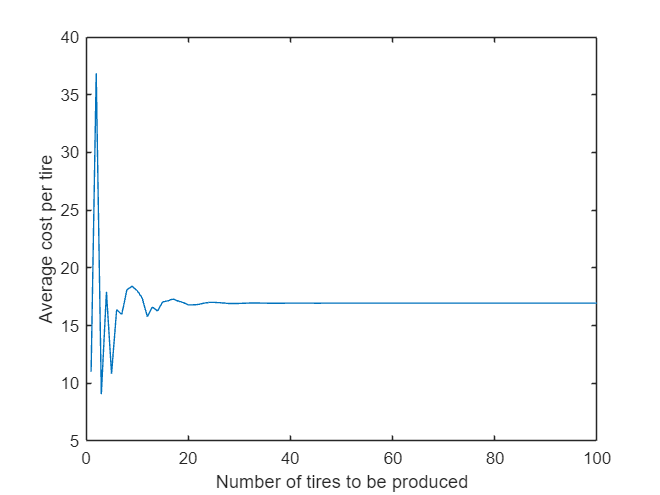

plot(1:100, avg_over_states(1:100));
xlabel("Number of tires to be produced");
ylabel("Average cost per tire");

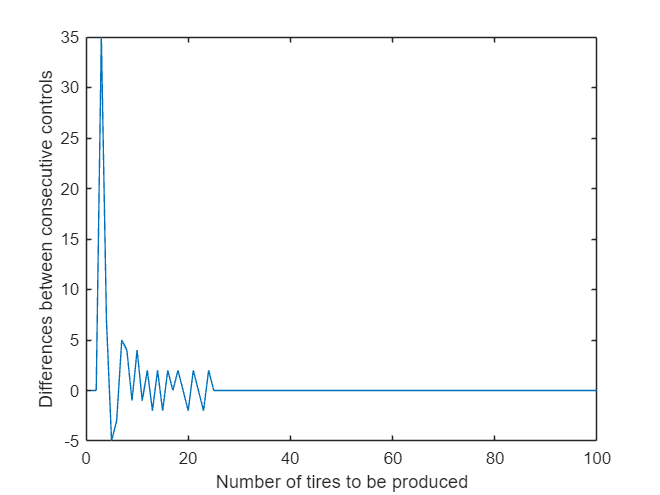

plot(1:100, policy_changes(1:100));
xlabel("Number of tires to be produced");
ylabel("Differences between consecutive controls");

control_matrices(:,:,1:2)

ans = 7×7×2 string array
ans(:,:,1) = 

    "0"    "0"    "0"    "0"    "0"    "0"    "0"
    "0"    "0"    "0"    "0"    "0"    "0"    "0"
    "0"    "0"    "0"    "0"    "0"    "0"    "0"
    "0"    "0"    "0"    "0"    "0"    "0"    "0"
    "0"    "0"    "0"    "0"    "0"    "0"    "0"
    "0"    "0"    "0"    "0"    "0"    "0"    "0"
    "0"    "0"    "0"    "0"    "0"    "0"    "0"


ans(:,:,2) = 

    "PE"    "PE"    "PE"    "PE"    "PE"    "PE"    "PE"
    "PE"    "PE"    "PE"    "PE"    "PF"    "PE"    "PF"
    "PE"    "PE"    "PE"    "PE"    "PF"    "PE"    "PF"
    "PE"    "PE"    "PE"    "PE"    "PE"    "PE"    "PF"
    "PE"    "PS"    "PS"    "PE"    "PE"    "PE"    "PF"
    "PE"    "PE"    "PE"    "PE"    "PE"    "PE"    "PF"
    "PE"    "PS"    "PS"    "PS"    "PS"    "PS"    "RE"


control_matrices(:,:,50:51)

ans = 7×7×2 string array
ans(:,:,1) = 

    "PB"    "PB"    "PB"    "PB"    "PB"    "PB"    "RS"
    "PB"    "PB"    "PB"    "PB"    "PB"    "PB"    "RS"
    "PB"    "PB"    "PB"    "PB"    "PB"    "PB"    "RS"
    "PB"    "PB"    "PB"    "PB"    "PB"    "PB"    "RS"
    "PB"    "PB"    "PB"    "PB"    "PB"    "PB"    "RS"
    "PB"    "PB"    "PB"    "PB"    "PB"    "PB"    "RB"
    "RF"    "RF"    "RF"    "RF"    "RF"    "RB"    "RB"


ans(:,:,2) = 

    "PB"    "PB"    "PB"    "PB"    "PB"    "PB"    "RS"
    "PB"    "PB"    "PB"    "PB"    "PB"    "PB"    "RS"
    "PB"    "PB"    "PB"    "PB"    "PB"    "PB"    "RS"
    "PB"    "PB"    "PB"    "PB"    "PB"    "PB"    "RS"
    "PB"    "PB"    "PB"    "PB"    "PB"    "PB"    "RS"
    "PB"    "PB"    "PB"    "PB"    "PB"    "PB"    "RB"
    "RF"    "RF"    "RF"    "RF"    "RF"    "RB"    "RB"
